# Create and Train a Deep Learning Model

Script for creating and training a deep learning network with the following properties:

Run this script to create the network layers, import training and validation data, and train the network. The network layers are stored in the workspace variable `layers`. The trained network is stored in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 05-May-2024 18:13:08

## Load Initial Parameters

Load parameters for network initialization. For transfer learning, the network initialization parameters are the parameters of the initial pretrained network.

trainingSetup = load("C:\Users\onugu\OneDrive\Masaüstü\AlzheimerSınıflandırma\kodlar\matlab86myCNNrms.mat");

## Import Data

Import training and validation data.

imdsTrain = imageDatastore("C:\Users\onugu\OneDrive\Masaüstü\AlzheimerSınıflandırma\archive\Alzheimer_s Dataset","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation] = splitEachLabel(imdsTrain,0.7,"randomized");

% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([224 224 1],imdsTrain);
augimdsValidation = augmentedImageDatastore([224 224 1],imdsValidation);

## Set Training Options

Specify options to use when training.

opts = trainingOptions("rmsprop",...
    "ExecutionEnvironment","multi-gpu",...
    "InitialLearnRate",0.001,...
    "MaxEpochs",15,...
    "MiniBatchSize",64,...
    "Shuffle","every-epoch",...
    "Plots","training-progress",...
    "ValidationData",augimdsValidation);

## Create Array of Layers

layers = [
    imageInputLayer([224 224 1],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([2 2],"Name","maxpool","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv_1","Padding","same")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv_2","Padding","same")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv_3","Padding","same")
    reluLayer("Name","relu_3")
    maxPooling2dLayer([2 2],"Name","maxpool_3","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],32,"Name","conv_4","Padding","same")
    reluLayer("Name","relu_5")
    maxPooling2dLayer([2 2],"Name","maxpool_4","Padding","same","Stride",[2 2])
    convolution2dLayer([3 3],64,"Name","conv_5","Padding","same")
    reluLayer("Name","relu_6")
    maxPooling2dLayer([2 2],"Name","maxpool_5","Padding","same","Stride",[2 2])
    reluLayer("Name","relu_7")
    dropoutLayer(0.5,"Name","dropout")
    fullyConnectedLayer(4,"Name","fc_1","WeightLearnRateFactor",8)
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

## Train Network

Train the network using the specified options and training data.

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:05 |       51.56% |       14.01% |       4.1511 |      72.9761 |          0.0010 |
|       1 |          50 |       00:00:10 |       53.12% |       35.00% |       1.2303 |       1.1155 |          0.0010 |
|       2 |         100 |       00:00:15 |       37.50% |       50.00% |       1.1217 |       1.0390 |          0.0010 |
|       3 |         150 |       00:00:20 |       46.88% |       51.04% |       1.1684 |       1.0705 |          0.

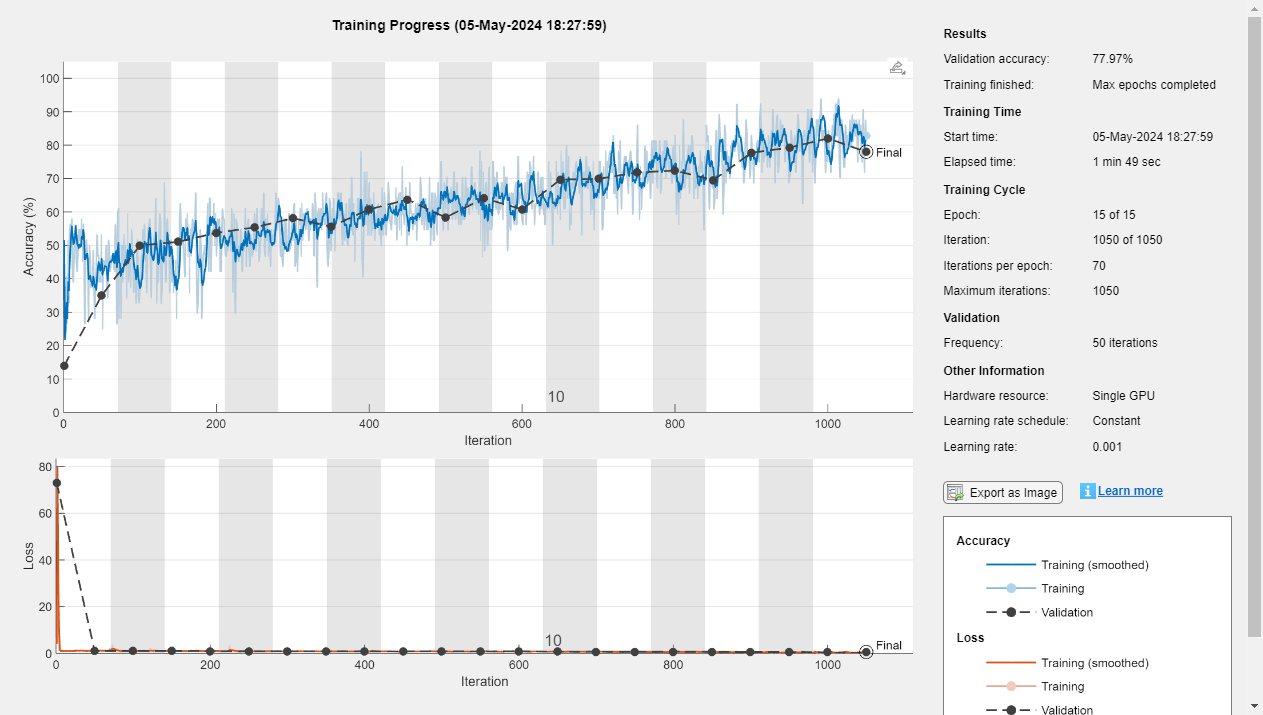

[myCNNRmsSuccess, traininfo] = trainNetwork(augimdsTrain,layers,opts);